%1
t = 0:0.05:6*pi;
x=sin(t);
y=2*cos(t);
 plot3(x,y,t)
grid on
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Пространственная спираль')

t0=(7*pi)/2;
x1=sin(t0)-cos(t0);
y1=2*cos(t0)-2*sin(t0)

y1 = 2.0000

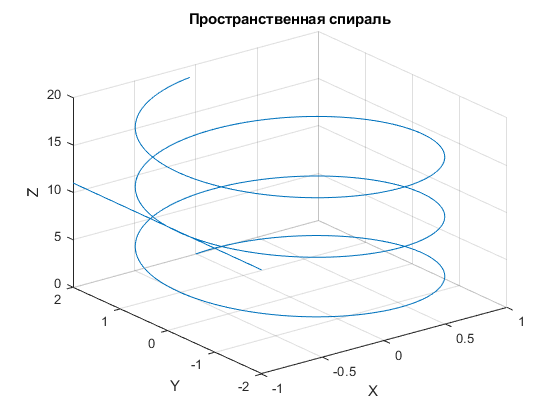

x2=sin(t0)+cos(t0);
y2=2*cos(t0)+2*sin(t0);
z1=t0;
z2=t0;
line([x1,x2],[y1,y2],[z1,z2]);
hold on
plot3(sin(t0),2*cos(t0),t0);

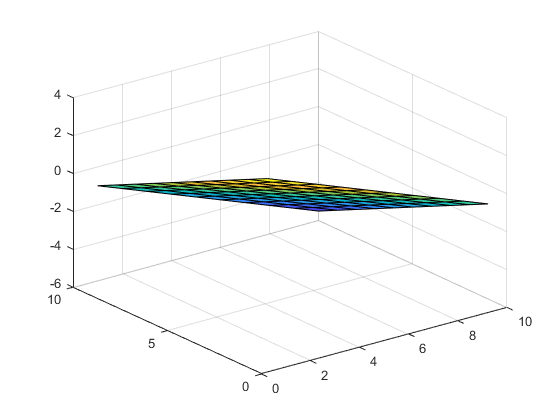

%1
point = [1,2,3];
normal = [1,1,2];

d = -point*normal';
[xx,yy]=ndgrid(1:10,1:10);
z = (-normal(1)*xx - normal(2)*yy - d)/normal(3);

figure
surf(xx,yy,z)

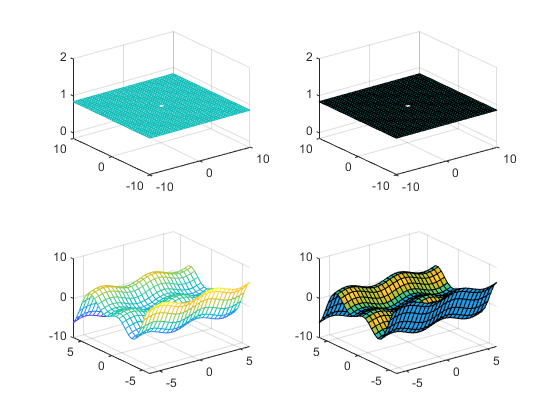

%2(a)
clear all
x=-10:0.5:10;
y=-10:0.5:10;
a=1;
subplot(2,2,1)
[X,Y]=meshgrid(x,y);
Z=a*sin(sqrt(X.^2+Y.^2)./sqrt(X.^2+Y.^2));
mesh(X,Y,Z);
subplot(2,2,2);
surf(X,Y,Z);

%2(b)
subplot(2,2,3)
x=-2*pi:0.5:2*pi;
y=-2*pi:0.5:2*pi;
[X,Y]=meshgrid(x,y);
Z= -X*sin(X)-Y.*cos(Y);
mesh(X,Y,Z);
subplot(2,2,4);
surfl(X,Y,Z);